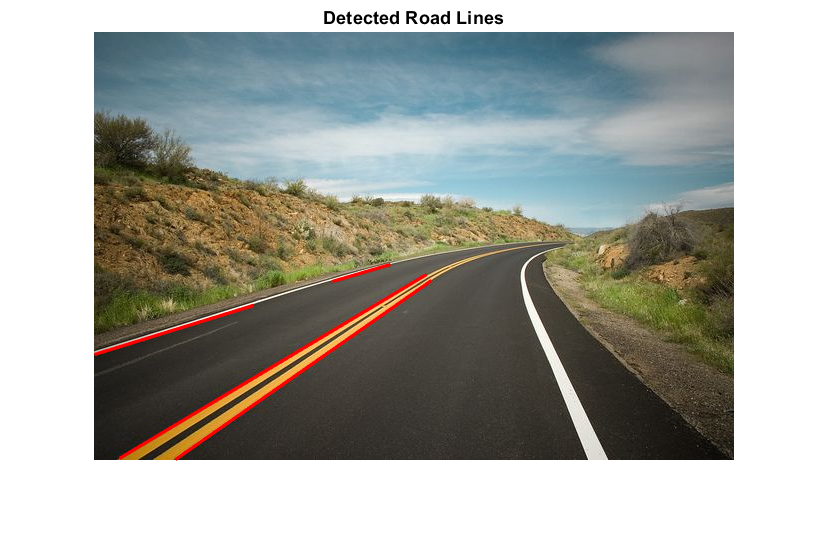

% Read the input image (replace with your road image file)
img = imread('RRR.jpg');

% Convert the image to grayscale (if it's not already)
grayImg = rgb2gray(img);

% Apply a Gaussian filter to smooth the image and remove noise
gaussianFiltered = imgaussfilt(grayImg, 2); % Sigma = 2 for smoothing

% Apply Sobel edge detection to detect edges in the image
sobelEdges = edge(gaussianFiltered, 'Sobel');

% Perform Hough Transform to detect straight lines
[H, theta, rho] = hough(sobelEdges);

% Find peaks in the Hough transform (possible line locations)
peaks = houghpeaks(H, 5); % Number of peaks to consider (tune this as needed)

% Find the lines using the Hough transform and the peaks
lines = houghlines(sobelEdges, theta, rho, peaks);

% Display the original image
figure;
imshow(img);
hold on;

% Plot the detected lines on the image
for k = 1:length(lines)
    % Get the start and end points of the line
    xy = [lines(k).point1; lines(k).point2];
    plot(xy(:,1), xy(:,2), 'LineWidth', 2, 'Color', 'red');
end

title('Detected Road Lines');
hold off;